clear all, close all, clc

**############# ############# ############# ############# ############# #############**

## Prob. 2

### a) Electrons

Given,

E = 10;         % energy, electron; MeV

Now, from Textbook, Table 3.6-

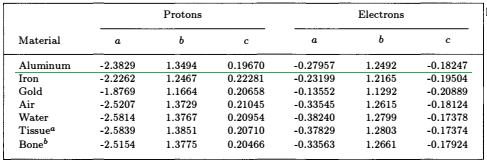

From the above table, for electron in Al, we have-

a = -0.27957;
b = +1.2492;
c = -0.18427;

Here,

x = log10(E)

x = 1

Then, $y=a+\textrm{bx}+{\textrm{cx}}^2$

y = a + b*x + c*x^2

y = 0.7854

So, $y=\log_{10} \left(\rho \Lambda \right)$

rh_L_e = 10^y                 % CSDA range of e', in Al; g/cm^2

rh_L_e = 6.1004

Now, let's verify this from Textbook, Figure 3.15

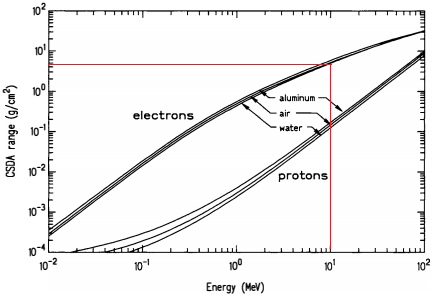

From the above figure it is seen that $\rho \Lambda$is approximatly 5 g/cm^2, which is nearly what we got from the equation in the prior section. (Verified)

### b) Protons

Given,

E = 10;         % energy, proton; MeV

From the  table, for prtoton in Al, we have-

a = -2.3829;
b = +1.3494;
c = +0.1967;

Then,

x = log10(E)

x = 1

y = a + b*x + c*x^2

y = -0.8368

So, $y=\log_{10} \left(\rho \Lambda \right)$

rh_L_p = 10^y                 % CSDA range of p', in Al; g/cm^2

rh_L_p = 0.1456

Now, let's verify this from Textbook, Figure 3.15

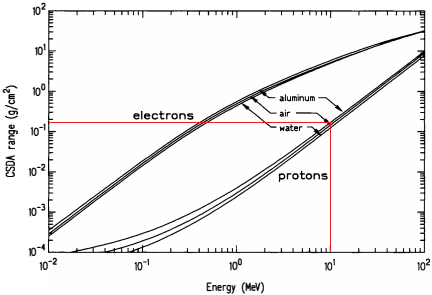

We can tell from the figure that  rh_L_p = 0.18 g/cm^2. So, it is verified also against result got from the equation. (Verified)

### c) Alpha Particles

Let's look at the following equational development-


$$v=k\frac{m}{z}\frac{Z}{A}$$


Here, Z = atomic number for stopping medium (13 for Al)

A = mass number for stopping medium (27 for Al)

m = mass for particle that’s going to be stopped (4 for a)

z = atomic number of particle to be stopped ( 2 for a)

k = constant of proportionality

This implies-


$$\frac{v_2 }{v_1 }=\frac{m_{2\ } /m_{1\ } }{z_2^2 /z_1^2 }\frac{Z_2 /Z_1 }{A_2 /A_1 }$$


Now, taking 1 for proton in aluminum and 2 for a-particle in aluminum, we have-


$$\frac{v_2 }{v_1 }=\frac{4}{4}\ldotp \frac{1}{1}=1$$


Then again,


$$E=0.5\ mv^2$$


which means-


$$\frac{E_2 }{E_1 }=\frac{m_2 }{m_1 }\;\frac{v_2^{2\;} }{v_1^{2\;} }=4\ldotp 1$$


Or, $E_1 =\frac{E_2 }{4}$

This means, a 10 MeV has the same range in Al, for a 2.5 MeV proton in Al. Now, let's calculate the range for 2.5 Mev $\alpha \;$  

E = 2.5;            % energy, proton (alf equivalent); MeV

From the  table, for prtoton in Al, we have-

a = -2.3829;
b = +1.3494;
c = +0.1967;

Then,

x = log10(E)

x = 0.3979

y = a + b*x + c*x^2

y = -1.8148

So, $y=\log_{10} \left(\rho \Lambda \right)$

rh_L_a = 10^y                 % CSDA range of alfa, in Al; g/cm^2

rh_L_a = 0.0153

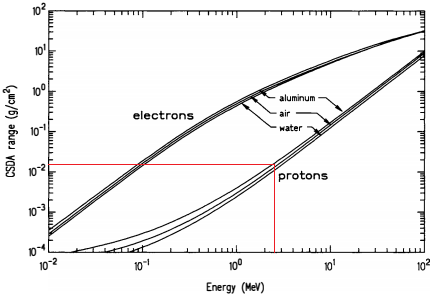

We can tell from the figure that  rh_L_a = 0.015 g/cm^2. So, it is verified also against result got from the equation. (Verified)

**############# ############# ############# ############# ############# #############**

## Prob. 3

Given,

t_o1 = 325;                 % operating time; day
t_o1 = t_o1*24*60^2;        % sec
t_o2 = 300;                 % ; d
t_o2 = t_o2*24*60^2;        % sec
P_o1 = 3*1e6;               % power output for first operation; W, J/s
  J_MeV = 1.6e-13;          % J/MeV
P_o1 = P_o1 /J_MeV          % power output, MeV/s

P_o1 = 1.8750e+19


t_s1 = 60;                  % shutdown period; day
t_s1 = t_s1*24*60^2;        % s
t_s2 = 250;                 % d
t_s2 = t_s2*24*60^2;        % s
P_o2 = 7.5*1e6;             % power output for 2nd operation; W
P_o2 = P_o2 /J_MeV          % power output, MeV/s

P_o2 = 4.6875e+19

So, let's calculate the totality

t_o = t_o1 + t_o2           % sec

t_o = 54000000

t_s = t_s1 + t_s2           % sec

t_s = 26784000

### a)

Now, we know from the book, equation 4.16-


$$\Gamma {\left(t_o ,t_s \right)}=P_o \sum_{i=1}^{N_j } \frac{\alpha_{ij} }{\lambda_{ij} }e^{-\lambda_{ij} t_s } \left(1-e^{-\lambda_{ij} t_o } \right)$$


Let's calculate the total energy release through $\gamma \;$decay. Now, from textbook AG-TG.3 (Appendix G, Table G.3)

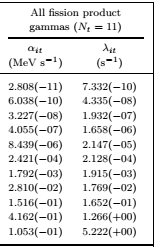

Table: total gamma and beta decay constants for fission products resultring from thermal neutron induced fission of U-235

Here, picking up the values for gamma

al_gm = [2.808E-11, 6.038E-10, 3.227E-8, 4.055E-7, 8.439E-6, 2.421E-4, 1.792E-3, 2.810E-2, 1.516E-1, 4.162E-1, 1.053E-1];
lm_gm = [7.332E-10, 4.335E-8,  1.932E-7, 1.658E-6, 2.147E-5, 2.128E-4, 1.915E-3, 1.769E-2, 1.652E-1, 1.266E0,  5.222E0];

 So, let's vectorize the following expression-


$$\textrm{Ex}=\frac{\alpha_{ij} }{\lambda_{ij} }e^{-\lambda_{ij} t_s } \left(1-e^{-\lambda_{ij} t_o } \right)$$


- for different values of operating time and corresponding shutdown time

gamma1 = (al_gm./lm_gm).*exp(-lm_gm.*t_s1).*(1 - exp(-lm_gm.*t_o1));
gamma2 = (al_gm./lm_gm).*exp(-lm_gm.*t_s2).*(1 - exp(-lm_gm.*t_o2));

Then, let's sum up the values for $\gamma \;$

sum_gm1 = sum(gamma1);
sum_gm2 = sum(gamma2);

Then, let's find the decay energy release  rate-

P_1 = P_o1*sum_gm1              % energy release rate; MeV/s

P_1 = 1.3075e+18

P_2 = P_o2*sum_gm2              % MeV/s

P_2 = 3.2582e+17

So, total energy release rate-

P = P_1 + P_2                   % MeV/s

P = 1.6334e+18

(Ans)

### b)

Now, from textbook AG-TG.1, we see, for emission between 2-3 MeV of gamma, only FP group N4 is responsible. Here-

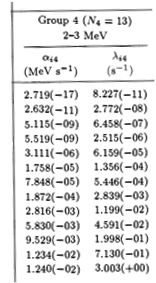

Now, let's tabulate them 

al_gm = [2.719e-17, 2.632e-11, 5.115e-09, 5.519e-09, 3.111e-06, 1.758e-05, 7.848e-05, 1.872e-04, 2.816e-03, 5.830e-03, 9.529e-03, 1.234e-02, 1.240e-02];
lm_gm = [8.227e-11, 2.772e-08, 6.458e-07, 2.515e-06, 6.159e-05, 1.356e-04, 5.446e-04, 2.839e-03, 1.199e-02, 4.591e-02, 1.998e-01, 7.130e-01, 3.003e+00];

Now again, let's vectorize the expression-


$$\textrm{Ex}=\frac{\alpha_{ij} }{\lambda_{ij} }e^{-\lambda_{ij} t_s } \left(1-e^{-\lambda_{ij} t_o } \right)$$


gamma1 = (al_gm./lm_gm).*exp(-lm_gm.*t_s1).*(1 - exp(-lm_gm.*t_o1));
gamma2 = (al_gm./lm_gm).*exp(-lm_gm.*t_s2).*(1 - exp(-lm_gm.*t_o2));

And then, sum it-

sum_gm1 = sum(gamma1);
sum_gm2 = sum(gamma2);

Now, let's find the decay energy release rate-

P_1 = P_o1*sum_gm1              % energy release rate; MeV/s

P_1 = 1.3562e+16

P_2 = P_o2*sum_gm2              % MeV/s

P_2 = 1.2535e+16

So, total energy release rate, via $\gamma \;$photons of 2 and 3 MeV-

P = P_1 + P_2                   % MeV/s

P = 2.6097e+16

(Ans) 

**############# ############# ############# ############# ############# #############**

## Prob. 4

### (a) for Natural Mo Target

We have the following equations, whereby T-99m is produced from Mo-98


$${}^1_0n+{}^{98}_{42}{Mo}\to {}^{99}_{42}{Mo}+\gamma$$



$${}^{99}_{42}{Mo}\to {}^0_{-1}{\beta }+{}^{99m}_{43}{Tc}$$


Now, let's calculate the amount of ${}^{98}_{42}{Mo}$ in the sample

m = 1;          % mass of Mo sample; g
M = 98;        % molar mass; g/mol

Now, from Textbook AC-TC2

a = 23.4*1e-2;             % isotopic abundance
Na = 6.02e23;               % Avogadro's number

Now, we know, for number of isotopes Mo-98 in the sample-


$$N=\frac{m}{M}\;N_a \;\;a$$


N = m/M *Na*a             % no. of Mo-98 in sample

N = 1.4374e+21

These ${}^{98}_{42}{Mo}$ is irratdiated by neutrons to become ${}^{99}_{42}{Mo}$. For this, now lets calculate activated nuclides of Mo-98

${\textrm{Nu}}_r =N\;\sigma_{\gamma \;} \;\phi_{\textrm{nu}} \;$    ${\textrm{Nu}}_r =$ no. of activated nuclides /sec

phi = 1e14;                 % nu' flux; cm^-2.s^-1
% dt = 1;                   % irradiation time; s
sg = 0.13;                  % activation CS; b
sg = sg*1e-24;              % cm^-2
N_ar = N *sg*phi            % nuclide activation rate; #/s

N_ar = 1.8687e+10

**Saturation Acivity:** It's the maximum possible activity, a radionuclide group can reach, under constant exposure of radiaton. 

It's given that the saturation activity is reached at 5 times the parent half life. Here, parent is Mo-99

t_h_p = 65.94;              % half-life of Mo-99; hr
t_h_p = t_h_p*60^2          % sec

t_h_p = 237384

lm_p = log(2)/t_h_p         % decay const. of Mo-99; s^-1

lm_p = 2.9199e-06

And, for daughter Tc-99 m

t_h_d = 6;                  % HL of Tc-99m; hr
t_h_d = t_h_d*60^2          % sec

t_h_d = 21600

lm_d = log(2)/t_h_d         % decay const. of Tc-99m; s^-1

lm_d = 3.2090e-05

So, the irradiation time has to be, at least, the 5 times of that

t_ir = t_h_p*5               % irradiation time; sec

t_ir = 1186920

So, within that time of exposure, the activated nuclides would be-

Nu = N_ar *t_ir            % no. of activated Mo-98 /produced Mo-99

Nu = 2.2179e+16

Now, we know the follows-

 $A_p \left(0\right)=N\left(0\right)\;\lambda_p$         $A_p \left(0\right)=$ Activity of parent (Mo-99) at the beginning moment of decaying. 

    Here, $\lambda =$ decay const.; $t=$ decay time

So, here, when the saturation activity is reached, the neutron exposure is truned off. 

Now, let's calculate the activity of parent (Mo-99) at beginning the beginning moment of decaying. 

A_p0 = Nu *lm_p           % parent's initial activity; dps

A_p0 = 6.4763e+10

**Transient Equilibrium:** Hereby, the parent and daughther each reach at equal amount of activity

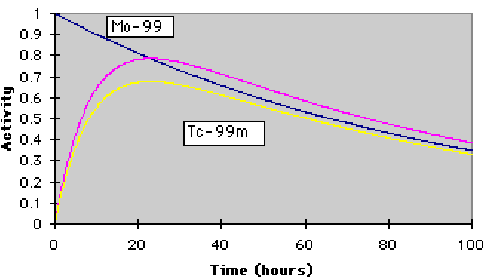

Given, Tc-99m is present under Transient Equilibrium after 24 hours of decay. So-

t = 24*60^2;                    % decay time; s

Now, for Transient Equilibrium-


$$A_d \left(t\right)=A_p \left(0\right)\frac{\lambda_d }{\lambda_d -\lambda_p }\left(e^{-\lambda_p t\;} -e^{-\lambda_d t\;} \right)$$


    C = lm_d /(lm_d - lm_p)                     % defining const. 

C = 1.1001

A_dt = A_p0 *C *( exp(-lm_p*t) - exp(-lm_d*t) )         % Activity of T-99m, @ t; dps

A_dt = 5.0907e+10

Now, let's convert it into Ci

    Bq_Ci = 37e9;           % Bq/Ci
A_dt = A_dt/Bq_Ci           % Ci

A_dt = 1.3759

So, we see, it's not sufficient enough to reach the Specificiation Amount, which is 10 Ci

### (b) for 20% Enriched Uranium Target

Let's consider the following fissioning path

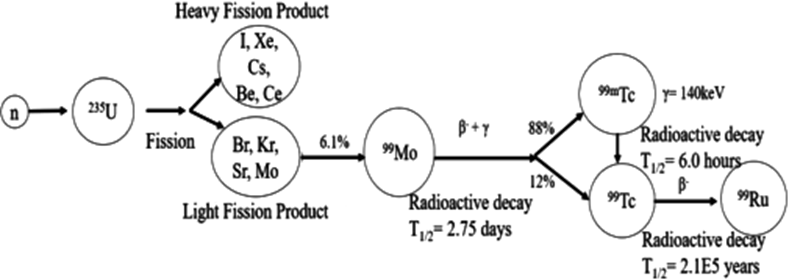

m = 1;              % mass of U-235;
M = 235;            % molar mass; g/mol
a = 20e-2;          % enrichment, percentage

So, we have, no. of fissionable U-235 in the sample-


$$N=\frac{m}{M}\;N_a \;\;a$$


N = m/M *Na *a          % no. of fissionable isotopes; #

N = 5.1234e+20

Now, from Textbook AC-TC1

sg_f = 587;             % fission CS; b
sg_f = sg_f*10^-24;     % cm^-2

So, we have, the fissioning rate-


$${\textrm{Nu}}_r =N\;\sigma_{\gamma \;} \;\phi_{\textrm{nu}}$$


phi = 1e14;             % nu' flux density; cm^-2.s^-1
N_fr = N *sg_f* phi     % fissioning rate; #/s

N_fr = 3.0074e+13

As, we see the follows that, only 6.1% of the direct fission prodcut convert into Mo, so, we can say

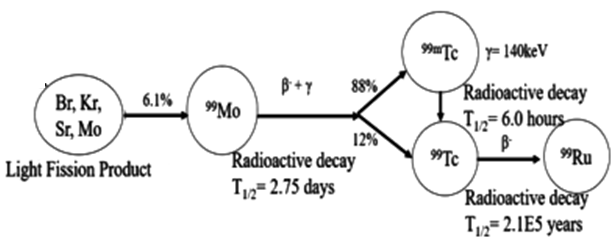

N_ar = N_fr*0.061           % Mo-99 prodcution rate

N_ar = 1.8345e+12

And, from the part (a), we get the followings for parent is Mo-99

t_h_p = 65.94;              % half-life of Mo-99; hr
t_h_p = t_h_p*60^2          % sec

t_h_p = 237384

lm_p = log(2)/t_h_p         % decay const. of Mo-99; s^-1

lm_p = 2.9199e-06

And, for daughter Tc-99 m

t_h_d = 6;                  % HL of Tc-99m; hr
t_h_d = t_h_d*60^2          % sec

t_h_d = 21600

lm_d = log(2)/t_h_d         % decay const. of Tc-99m; s^-1

lm_d = 3.2090e-05

And, irradiation time-

t_ir = t_h_p*5               % irradiation time; sec

t_ir = 1186920

Then, the number of activated Mo-99

Nu = N_ar *t_ir

Nu = 2.1774e+18

Similary, we have-

A_p0 = Nu *lm_p             % parent's initial activity; dps

A_p0 = 6.3580e+12

t = 24*60^2;                % decay time; s

So, for transient equilibrium to happen-


$$A_d \left(t\right)=A_p \left(0\right)\frac{\lambda_d }{\lambda_d -\lambda_p }\left(e^{-\lambda_p t\;} -e^{-\lambda_d t\;} \right)$$


    C = lm_d /(lm_d - lm_p);                    % defining const. 
A_dt = A_p0 *C *( exp(-lm_p*t) - exp(-lm_d*t) )         % Activity of T-99m, @ t; dps

A_dt = 4.9977e+12

Now, transforming it to Ci

A_dt = A_dt /Bq_Ci                              % Ci

A_dt = 135.0734

So, we find, in this case- the activity is sufficient enough to meet the specfication of 10 Ci

(Shown)

**############# ############# ############# ############# ############# #############**

## Prob. 6

### a)

**Deep Dose Equivalent Index: **It is the dose equivalent at a tissue depth of 1 cm (1000 mg/cm2) due to external whole-body exposure to ionizing radiation. 

Given,

A = 1;               % activity, of Co-60; Ci
Sp = A*37e9          % souce activitiy; Bq, #/s

Sp = 3.7000e+10

Now, we know-

$\phi \;=\frac{S_p }{A}$         A = area; $S_p =$ source activity

r = 1*100;              % radius; cm
Ar = 4*pi*r^2;          % sphere surface area; cm^2
ph = Sp /Ar             % photon flux; #/cm^2.s

ph = 2.9444e+05

t = 60;                 % exposure time; sec
Ph = ph*t               % fluence/hr; #/cm^2.hr

Ph = 1.7666e+07

**i)**

Using nuclide chart, for Co-60, we get-

E_g = 1.3325;           % g-energy; MeV

Then, we can use following figure to calculate dose-cm^2 for the given gamma energy (Source: Lectures: NE 590; Dr. Robert Hayes) of Co-60. 

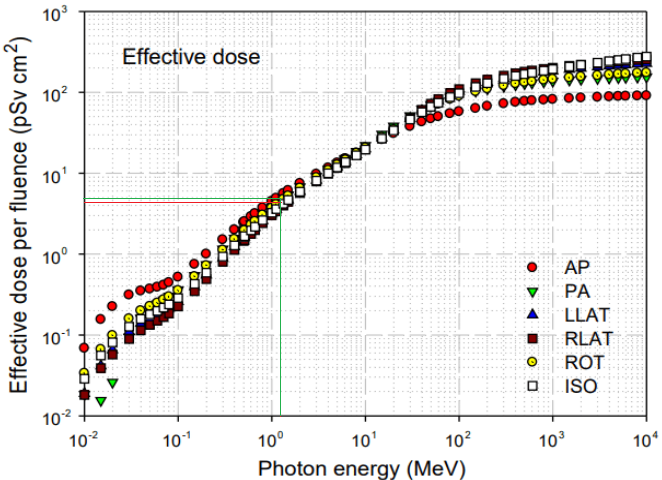

Here, we get for spherical symetry, the isometric condtion (ISO)

D_Ph = 4.5;                 % dose per fluence; pSv.cm^2
D_r = D_Ph *Ph              % dose per hr; pSv/hr

D_r = 7.9498e+07

D_r = D_r *1e-12;           % Sv/hr
D_r = D_r*100               % rem/hr

D_r = 0.0079

So, now let's find the Deep Dose Index rate, $H_{\textrm{Dr}\;} ={\textrm{DDE}}_r =\dot{D} \times W_t \times Q$

W_T = 1;                % tissue weighting factor for whole body
Q = 1;                  % quality factor, photon
H_Dr = D_r *W_T *Q      % DDE_r; rem/hr

H_Dr = 0.0079

**ii)**

From the same above figure, we find that, for rotational projection-

D_Ph = 5.0;                 % dose per fluence; pSv.cm^2
D_r = D_Ph *Ph              % dose per hr; pSv/hr

D_r = 8.8331e+07

D_r = D_r *1e-12;           % Sv/hr
D_r = D_r*100               % dose rate; rem/hr

D_r = 0.0088

So, the Equivalent Dose Rate $H_E$ would be-

H_E = D_r*Q                % equivalent dose rate; rem/hr

H_E = 0.0088

**iii)**

We know-


$$\dot{\;X} =\frac{6\textrm{CEN}}{d^2 }$$


C = 1;                  % activity; Ci
E = 1.3325;             % g-energy; MeV
N = 1;                  % branching ratio
d = 1*3.28;             % distance; ft

So, the exposure bemomes-

X_d = 6*C*E*N/d^2       % exposure; R/hr

X_d = 0.7431

**iv)**

The effective dose would be-

Ef = D_r *Q*W_T             % effectived dose; rem/hr

Ef = 0.0088

### v)

**Deep Dose Equivalent Index** ($H_D$): It is a measure of external radiation exposure at a tissue, at the depth of 1 cm (1000 mg/cm^2)- due to external whole body exposure to ionizing radiation. 

**Equivalent Dose** ($H_E$): It's a measure of dose when it is multiplied by the tissue weighting factor (W_T) and adjusted for the radiation type (whether- photon, neutron). So it is

$H_E =D\times W_R \times W_T$    $W_R =$ radiation weighting factor; $W_T =$ tissue weighting factor

**Free Field Flux Density (H):** It is the dose equivalent, with no influence on the radiation field from the human body.

**Effectieve Dose (E):** It's the measure of dose when it counts the effect of dose for the whole body, instead of individual organs. So, it is-


$$H_E =D\times W_R \times \sum W_T \;$$


### b) 

*Please, see the first part of the pdf*